# **Proof of Concept**

**Notes: **It needs Yalmip and OSQP. Yalmip should install himself automatically both on Windows and Linux. OSQP should automatically install on Linux, if there are any problems read the README. On Windows you need to install OSQP yourself.

There are TONs of other parameters and configuration you can tune and adapt, but atm you need to search them yourself.

clc;
clear variables;

## **Initialization**

%% INIT

% Instantiate main Class:
hpc = hpc_lab;

% Rows and Columns
hpc.Nv = 16;
hpc.Nh = 4;

% Core number
hpc.Nc = hpc.Nv*hpc.Nh; %20

% Number of Voltage Domains
hpc.vd = 5; %hpc.Nc;

% How the cores are distributed per domain
%hpc.VDom = ... ;
% Alternatively
hpc.default_VDom_config();

% Default Floorplan and Parameter deviation vector
hpc.default_floorplan_config();
hpc.create_model_deviation();

%Decide simulation frequency (discrete timing)
hpc.Ts = 5e-5;

%Decide total simulation time
hpc.tsim = 2;

%Presence/Absence of sensor noise:
hpc.sensor_noise = 1;

%Thermal model version
hpc.model_ver = 0;

#### After the configuration of the Thermal Model, run the model creation & others

hpc.model_init();
hpc.create_core_pw_noise();

#### Choose targets

% Initial Temperature condition
hpc.t_init = (hpc.temp_amb+10)*ones(hpc.Ns,1);

%Input maximum frequency
hpc.Ts_target;

tt = min(ceil(hpc.tsim / hpc.Ts_target)+1, (hpc.tsim/1e-4+1));

% Target Frequency Trajectory
hpc.frtrc = 3.45 * ones(tt, hpc.Nc);

%Target Power Budget
hpc.tot_pw_budget = 450/36*hpc.Nc*ones(tt,1);

tu = ceil(tt/4);
hpc.tot_pw_budget(tu+1:2*tu) = 2*hpc.Nc;
hpc.tot_pw_budget(2*tu+1:3*tu) = 5*hpc.Nc;
hpc.tot_pw_budget(3*tu+1:3*tu+ceil(tu/2)) = 3*hpc.Nc;
hpc.tot_pw_budget(3*tu+ceil(tu/2)+1:end) = 8*hpc.Nc;
5
hpc.quad_pw_budget = 450/36*hpc.Nc*ones(2,hpc.vd);

%Others, TODO
hpc.min_pw_red = 0.6;

#### After all the configurations are done, running the checks:

hpc.anteSimCheckTM();
hpc.anteSimCheckLab();
hpc.anteSimCheckPM();

## Run Autonomous thermal simulation

% Total time of simulation (s)
tsim_aut = 10;

% Changing Ts to improve the speed of simulation
%{
hpc.Ts = 250e-6;
hpc.model_init();
hpc.sim_tm_autonomous(tsim_aut)
hpc.Ts = 5e-5;
hpc.model_init();
%}

### **Generate Workload trace:**

%Probability of each workload type [idle, int, float, mem, vec]
hpc.wl_prob = [0.01 0.01 0.01 0.5 0.5]; %[0.0345 0.3448 0.3448 0.2414 0.0345];

%Minimum execution time (us) of each workload type
hpc.wl_min_exec_us = [510 100 100 480 520];	

%Mean execution time (us) of each workload type
hpc.wl_mean_exec_us = [120e2 210e1 180e1 560e2 1.2e6/1e1];

%Generate it
hpc.wltrc = hpc.generate_wl_trace(hpc.Nc, hpc.tsim, hpc.F_max, 0);


## **Controllers**

addpath('Controllers/');

## **Fuzzy Controller**

ctrl = Fuzzy;
ctrl.C = hpc.C;

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-4;


%Launch Simulation
tic;
hpc.simulation(ctrl,1);
toc;

## **SotA / CP MPC**

ctrl = cp_mpc;
ctrl.C = eye(hpc.Ns);

ctrl.save_solver_stats = 1;

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-3;
%ctrl.Nhzn = 20;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.Rt = R_coeff*eye(hpc.Nc);

%Others
ctrl.Rs = zeros(hpc.Nc);
ctrl.R = zeros(hpc.Nc);
ctrl.Q = zeros(hpc.Ns);

%Launch Simulation
tic;
[x, u, f, v, w] = hpc.simulation(ctrl,1);
res = hpc.stats_analysis(ctrl, x, u, f, v, w);
toc;

## **My-current-research MPC**

ctrl = black_wolf;
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-3;
%ctrl.Nhzn = 20;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 80; %absolute value
R_shared = 15;%20; % R_coeff/0.2;
R_track = 1;
Q_coeff = 6;%1e-2%2.5; 

% Create matrixes
ctrl.R = R_coeff*eye(hpc.Nc);
ctrl.Rt = R_track*eye(hpc.Nc);
ctrl.Rs = zeros(hpc.Nc);
for v=1:hpc.vd
	%Here I could create an accumulation thing that need to be
	%optimized (e.g. reduced) that contains the deltaF among quadrant 
	ctrl.Rs = ctrl.Rs + hpc.VDom(:,v)*hpc.VDom(:,v)' / sum(hpc.VDom(:,v))^2 * R_shared;
end
%TODO: Assuming that the diagonal is full
ctrl.Rs(~eye(size(ctrl.Rs))) = ctrl.Rs(~eye(size(ctrl.Rs))) * (-1);
cores_per_dom = sum(hpc.VDom);
ctrl.Rs(logical(eye(size(ctrl.Rs)))) = ctrl.Rs(~~eye(size(ctrl.Rs))) .* hpc.VDom*cores_per_dom'; %here I need ~~ to converto to logical values

ctrl.Q = (Q_coeff)*eye(hpc.Ns);

%{
Ew = R_coeff;
bm = Ew/2*eye(hpc.Nc);
bM = [zeros(hpc.Nc) bm; 
       bm zeros(hpc.Nc)];
ctrl.RE = [bM zeros(size(bM));
            zeros(size(bM)) bM];
%}


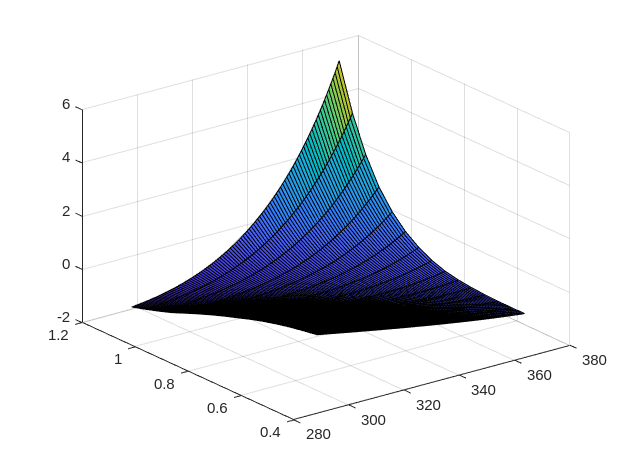

Final Centroids:
  325.9829    0.7364   -0.3164
  331.4380    0.7800   -0.4312
  338.8608    0.7700   -0.7733
  340.1476    0.8714   -1.0849
  322.4570    0.7125   -0.1972
  328.9709    0.7420   -0.4987
  350.4911    0.7500   -1.0003
  329.7300    0.7000   -0.4640
  349.4802    0.7614   -0.9676
  341.9008    0.7667   -0.8934
  312.1697    1.0762   -1.4741
  343.0236    0.7875   -0.9034
  340.0663    0.7375   -0.8024
  336.5028    0.7583   -0.7373
  340.9486    0.7684   -0.8569
  357.1234    0.7532   -1.0248
  363.0920    1.1469    1.6357
  320.4185    0.6950   -0.0368
  327.8576    1.0033   -1.1642
  302.1750    1.2000   -1.8683
  364.6373    1.1643    2.2670
  367.7780    1.1769    3.1847
  323.1479    0.7194   -0.1205
  330.8307    0.9625   -1.1204
  360.2455    1.1200    0.7872
  328.0220    0.9975   -1.1952
  323.7006    0.6833   -0.3963
  370.4932    1.2000    4.5483
  339.4126    0.8583   -1.0747
  333.9857    0.7578   -0.6647
  343.2535    0.7462   -0.8836
  321.1523    1.0438  

vtb =     0.2214    0.2214    0.0726   -0.0368   -0.1972   -0.3164   -0.4987   -0.6647   -0.8438   -1.0390   -1.2258   -1.4741   -1.6227   -1.7407   -1.8683
    0.2214    0.0726    0.0726   -0.0368   -0.1972   -0.3579   -0.4987   -0.6647   -0.8569   -1.0390   -1.2258   -1.4741   -1.6227   -1.7407   -1.8683
    0.2214    0.0726    0.0726   -0.0368   -0.1972   -0.3579   -0.5370   -0.7008   -0.8569   -1.0518   -1.2695   -1.4741   -1.6227   -1.7407   -1.8683
    0.2214    0.0726    0.0726   -0.1205   -0.1972   -0.3579   -0.5370   -0.7008   -0.8719   -1.0636   -1.2695   -1.4741   -1.6227   -1.7407   -1.8683
    0.2214    0.0726   -0.0368   -0.1205   -0.2624   -0.3963   -0.5370   -0.7008   -0.8836   -1.0747   -1.2695   -1.4741   -1.6227   -1.7407   -1.8683
    0.2214    0.0726   -0.0368   -0.1205   -0.2624   -0.3963   -0.5791   -0.7373   -0.8934   -1.0747   -1.2695   -1.4741   -1.6227   -1.7407   -1.8683
    0.2214    0.0726   -0.0368   -0.1205   -0.2624   -0.3963   -0.5791   -0.7373   -0.90

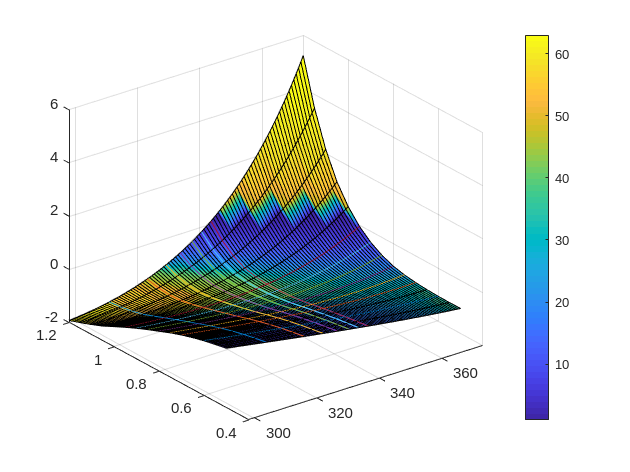

%Launch Simulation
tic;
[x, u, f, v, w] = hpc.simulation(ctrl,1);

toc;


ctrl = HLC;
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
ctrl.Ts_ctrl = hpc.Ts; %50e-3;
ctrl.hp = 5e-4;



%Launch Simulation
tic;
%hpc.simulation(ctrl,1);
toc;



wlpl = 1;

hpc.wltrc = zeros(hpc.Nc, hpc.ipl, length(hpc.wltrc));
hpc.wltrc(:,wlpl,:) = 1;

ctrl = dumb_test;
ctrl.C = eye(hpc.Ns);

ctrl.freq = 0.4;
%Launch Simulation
tic;
%hpc.simulation(ctrl,1);
toc;

ctrl.freq = 3.4;
%Launch Simulation
tic;
%hpc.simulation(ctrl,1);
toc;

